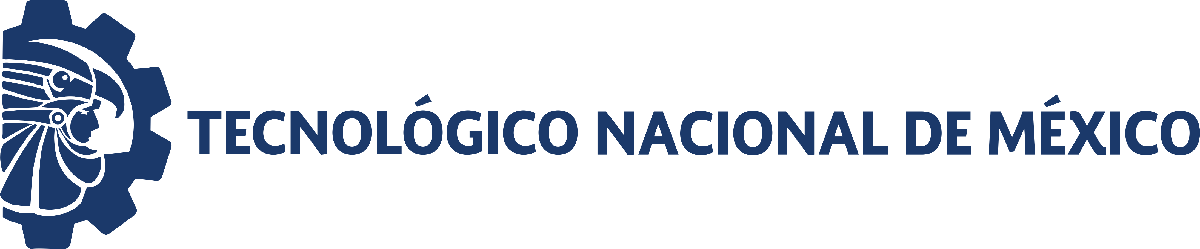                                 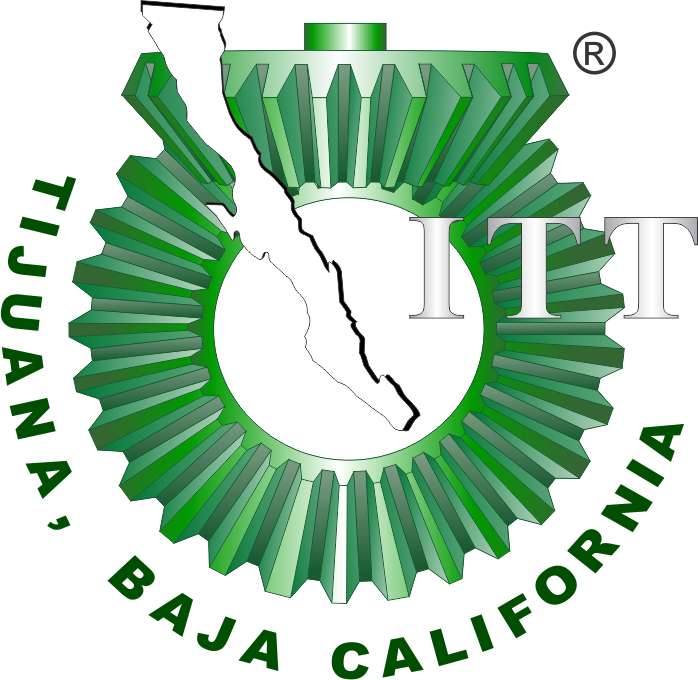

# Práctica 2: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[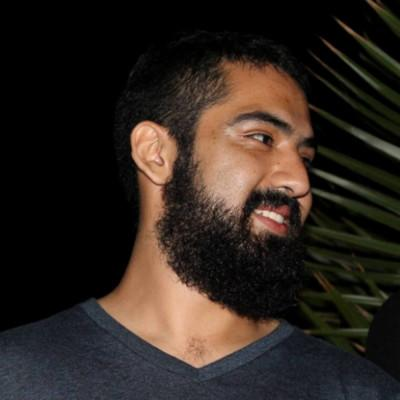]

Nombre del alumno: Dino Seañez Victor Silvano

Número de control: 20211964

Correo institucional: l20211964@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
file = 'Sistema';
open_system(file);
parameter.StopTime = '15';
parameter.Solver = 'ode15s';
parameter.MaxStep ='1E-3';
x = sim(file,parameter);
writematrix(x.PA,'signal.xlsx');

%set_param('Sistema/Ve(t)','VectorFormat','1-D array')

## Respuesta del sistema

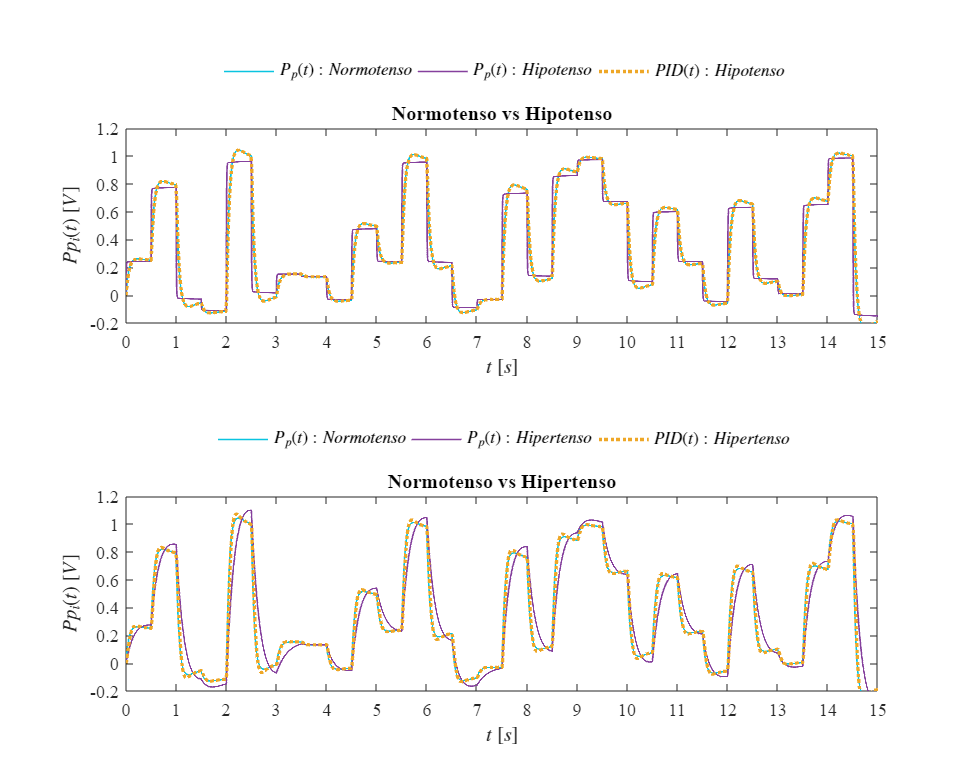

plotsignals(x.t,x.PP1,x.PP2,x.PP3,x.PID1,x.PID2)

## Respuesta del sistema

function plotsignals(t,PP1,PP2,PP3,PID1,PID2)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,25,20])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    
    powerrangers = [10,196,224;
                   133,64,157;
                   238,167,39]/255;
    colororder(powerrangers)

    subplot(2,1,1);box on; hold on;
    P = plot(t,PP1,'-',t,PP2,'-',t,PID1,':','LineWidth',1); set (P(3),'LineWidth',2)
    L = legend('$P_p(t):Normotenso$','$P_p(t):Hipotenso$','$PID(t):Hipotenso$');
    set(L,'Interpreter','Latex','FontSize',10,'location',...
        'NorthOutside','box','off','Orientation','Horizontal')

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$Pp_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)
    xlim([0,15]); xticks(0:1:15);
    ylim([-0.2,1.2]); yticks(-0.2:0.2:1.2)
    T = title("Normotenso vs Hipotenso"); set(T,'FontSize',10);
    set(gca,'FontName','Time News Roman','FontSize',11);


    subplot(2,1,2);box on; hold on;
    P = plot(t,PP1,'-',t,PP3,'-',t,PID2,':','LineWidth',1); set (P(3),'LineWidth',2)
    L = legend('$P_p(t):Normotenso$','$P_p(t):Hipertenso$','$PID(t):Hipertenso$');
    set(L,'Interpreter','Latex','FontSize',10,'location',...
        'NorthOutside','box','off','Orientation','Horizontal')

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$Pp_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)
    xlim([0,15]); xticks(0:1:15);
    ylim([-0.2,1.2]); yticks(-0.2:0.2:1.2)
    T = title("Normotenso vs Hipertenso"); set(T,'FontSize',10);
    set(gca,'FontName','Time News Roman','FontSize',11)


    exportgraphics(gcf,'Cardiovascular.pdf','ContentType','vector')
    %exportgraphics(gcf,[Signal,'.png'],'Resolution',600);
    %print(Signal,'-dsvg','-r600');
    %print(Signal,'-depsc','-r600')

end
